# Actividad

# Poryecto Regresion

#### Fecha:

fecha = datetime('now', 'Format', 'dd-MM-yyyy');
disp(['Fecha actualizada: ', char(fecha)])

Fecha actualizada: 06-07-2024


#### Objetivos:

- **Desde Open Energy Data Initiative, seleccionar un archivo CSV cualquiera de cualquier estado**

- [https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/](https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/)

- Definir la variable de salida y las variables de entrada del sistema

- Seleccionar Variables o caracteristicas empleando la matriz de correlacion **(Ajustar el threshold)**

- Seleccionar el algortimo de ML con un menos error de prediccion empleando el toolbox de Matlab Regression Learner

- Dividir el dataset en 70% para entrenar y 30% validar **(Ajustar el PSplit)**

- Usando el algoritmo de ML se entrena el modelo de regression (costo computacional)

- Cargar y validar el modelo entrenado

- Graficar el valor predecido vs el valor real

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

#### Librarys:

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- [https://es.mathworks.com/help/matlab/ref/ls.htm](https://es.mathworks.com/help/matlab/ref/ls.htm)

- [https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558](https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558)

## Paso 0: Descartar cualquier cambio realizado en el repositorio clonado

%Version Online, Opcion 1:
% Source Control -> Discard all changes
% Source Control -> git pull

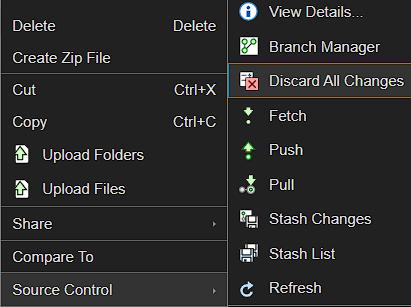

%Version Online, Opcion 2:
% repo = gitrepo;
% discardChanges(repo,repo.ModifiedFiles);
% Source Control -> git pull

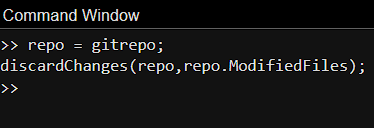

% Version para PC, en el Bash del Git:
% git status
% git reset --hard
% Git pull

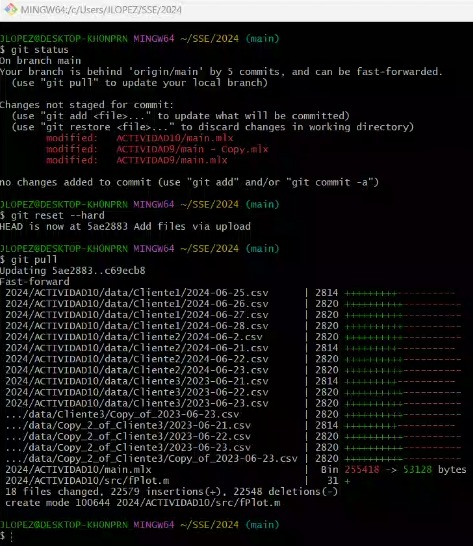

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window

## Paso 2.- Configuración de carpeta ./src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

## **Paso 3- Configuranción de carpeta de ./data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');

## **Paso 4- **Desde Open Energy Data Initiative, seleccionar un archivo CSV cualquiera de cualquier estado

### Informacion del dataset

- USA_AK_FAIRBANKS.csv

- USA_AK_Anchorage.Intl.AP.702730_TMY3/

cd data %Comando linux para entrar una carpeta
httpsUrl = "https://openei.org/datasets/files/961/pub/COMMERCIAL_LOAD_DATA_E_PLUS_OUTPUT/USA_AK_Anchorage.Intl.AP.702730_TMY3";
dataUrl = strcat(httpsUrl,"/RefBldgSmallHotelNew2004_v1.3_7.1_8A_USA_AK_FAIRBANKS.csv");
DataFile = "RefBldgSmallHotelNew2004_v1.3_7.1_8A_USA_AK_FAIRBANKS.csv";
DataFileFullPath = websave(DataFile,dataUrl);
cd .. %Comando linux para salir de la carpeta
clear httpsUrl dataUrl DataFile DataFileFullPath

## **Paso 4- Buscar los nombres y **Cargar los datos **de todos los archivos dentro de la carpeta ./data**

%Leer un archivo csv y lo carga como una tabla
filename = FindCSV(datapath);
maxnames=size(filename,1);
% Dataset es una tabla donde cada columna es una variable con su 
% respectivo nombre
index=1; % El archivo que quiero que lea desde la carpeta data
filename(index).name

ans = 'RefBldgSmallHotelNew2004_v1.3_7.1_8A_USA_AK_FAIRBANKS.csv'

Dataset=fLoadTableCSV_index(filename,datapath,index)

Dataset = 8760×11 table
         Date_Time         Electricity_Facility_kW__Hourly_    Fans_Electricity_kW__Hourly_    Cooling_Electricity_kW__Hourly_    Heating_Electricity_kW__Hourly_    InteriorLights_Electricity_kW__Hourly_    InteriorEquipment_Electricity_kW__Hourly_    Gas_Facility_kW__Hourly_    Heating_Gas_kW__Hourly_    InteriorEquipment_Gas_kW__Hourly_    WaterHeater_WaterSystems_Gas_kW__Hourly_
    ___________________    ________________________________    ____________________________    _______________________________    _______________________________    ______________________________________    _________________________________________    ________________________<

## **Paso 5- Extraer nombres de variables y crear datetime**

% Extraer todos los nombres de variables de la tabla
% Se hace el cast de cell a string
varnames=string(Dataset.Properties.VariableNames);
% Eliminar el primero nombbre de variable
varnames=varnames(2:end)';

% Esto es para eliminar el warning de los legend en el plot
%LegendNames=char(varnames);
%LegendNames=LegendNames(:,1:15);
%LegendNames=[LegendNames char(65*ones([size(varnames,1),1]))];
%LegendNames=string(LegendNames);

% Crear datatime con una frecuencia de muestreo de un dato por hora segun el
% dataset
%Time = Start Time: Step Time: End Time
time = datetime(2004, 1, 1):hours(1):datetime(2004, 12, 31);
% Se elimina el primer valor
time=time(1,2:end)';

% para agregar una nueva variables en la tabla
%Dataset.('Time_Stamp')=time;

## **Paso 6- Graficar todas las variables**

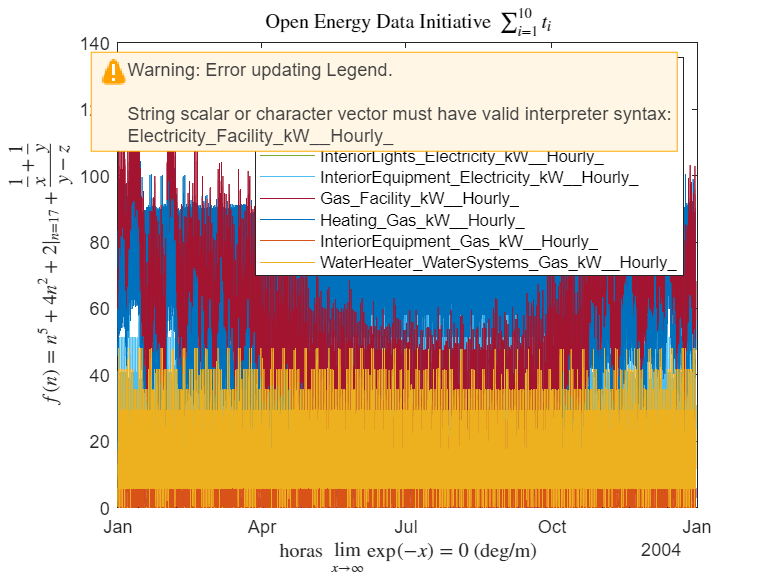

figure;
% Dataset
Variable1=Dataset.(varnames(1));
plot(time,Variable1)
hold on
Variable2=Dataset.(varnames(2));
plot(time,Variable2)
Variable3=Dataset.(varnames(3));
plot(time,Variable3)
Variable4=Dataset.(varnames(4));
plot(time,Variable4)
Variable5=Dataset.(varnames(5));
plot(time,Variable5)
Variable6=Dataset.(varnames(6));
plot(time,Variable6)
Variable7=Dataset.(varnames(7));
plot(time,Variable7)
Variable8=Dataset.(varnames(8));
plot(time,Variable8)
Variable9=Dataset.(varnames(9));
plot(time,Variable9)
Variable10=Dataset.(varnames(10));
plot(time,Variable10)

hold off
%legend(LegendNames);
legend(varnames);

% tambien se puede usar latex para los lables y titles
% https://en.wikibooks.org/wiki/LaTeX/Mathematics
title('Open Energy Data Initiative $ \sum_{i=1}^{10} t_i $', 'interpreter', 'latex');
xlabel('horas $ \lim\limits_{x \to \infty} \exp(-x) = 0 $ (deg/m)', 'interpreter', 'latex')
ylabel(' $ f(n) = n^5 + 4n^2 + 2 |_{n=17} + \frac{\frac{1}{x}+\frac{1}{y}}{y-z} $', 'interpreter', 'latex')

clear filename maxnames index
clear Variable1 Variable2 Variable3 Variable4 Variable5 Variable6 ...
    Variable7 Variable8 Variable9 Variable10

## **Paso 7- Definir la variable de salida y las variables de entrada del sistema**

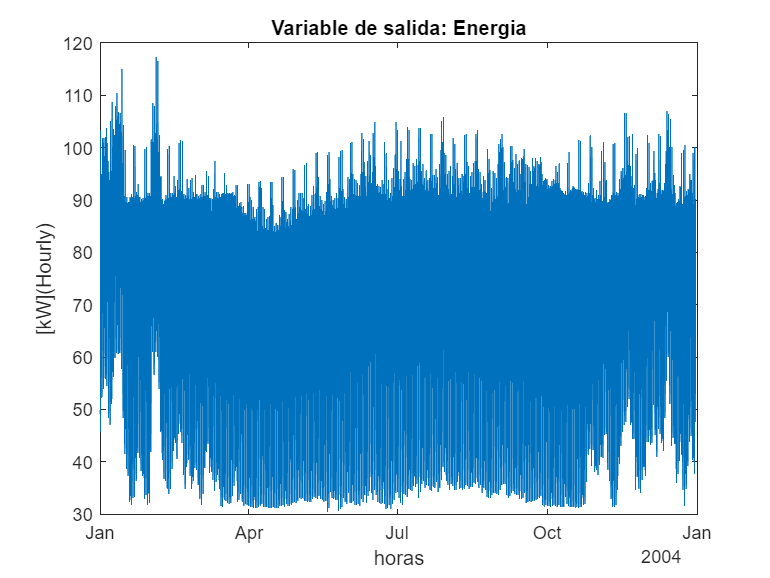

figure;
% Dataset
output=Dataset.(varnames(1));
plot(time,output)
title('Variable de salida: Energia');
xlabel('horas')
ylabel('[kW](Hourly)')

% Estamos usando las variables como caracteristicas
input=[Dataset.(varnames(2)) Dataset.(varnames(3))...
    Dataset.(varnames(4)) Dataset.(varnames(5))...
    Dataset.(varnames(6)) Dataset.(varnames(7))...
    Dataset.(varnames(8)) Dataset.(varnames(9))...
    Dataset.(varnames(10))];

## **Paso 9- Cambiar la resolucion temporal de los datos: Dias, Semanas, meses**

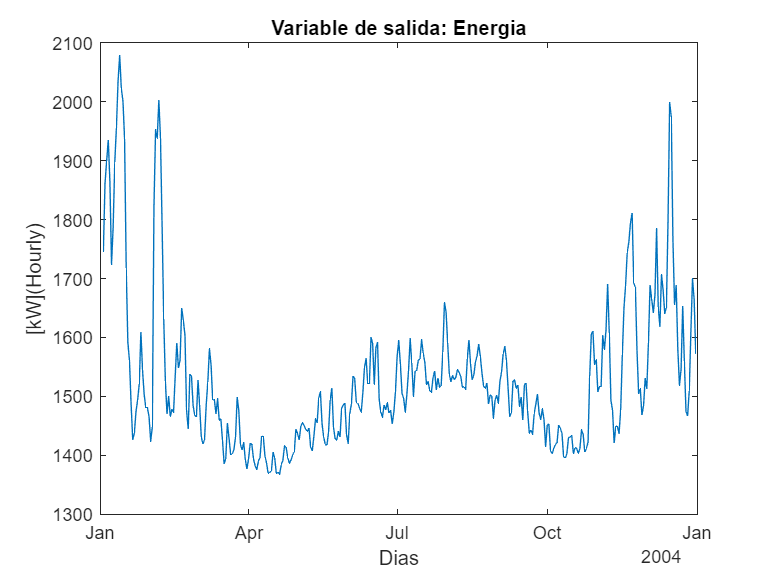

outputDias=[];
for i=1:24:size(output,1)-24
    outputDias=[outputDias;sum(output(i:i+24),1)];
end

%inputDias

% Crear datatime con una frecuencia de muestreo de un dato por hora segun el
% dataset
%Time = Start Time: Step Time: End Time
timeDias = datetime(2004, 1, 1):hours(24):datetime(2004, 12, 31);
% Se elimina el primer valor
timeDias=timeDias(1,3:end)';

figure;
plot(timeDias,outputDias)
title('Variable de salida: Energia');
xlabel('Dias')
ylabel('[kW](Hourly)')

## **Paso 8- Seleccionar Variables o caracteristicas**

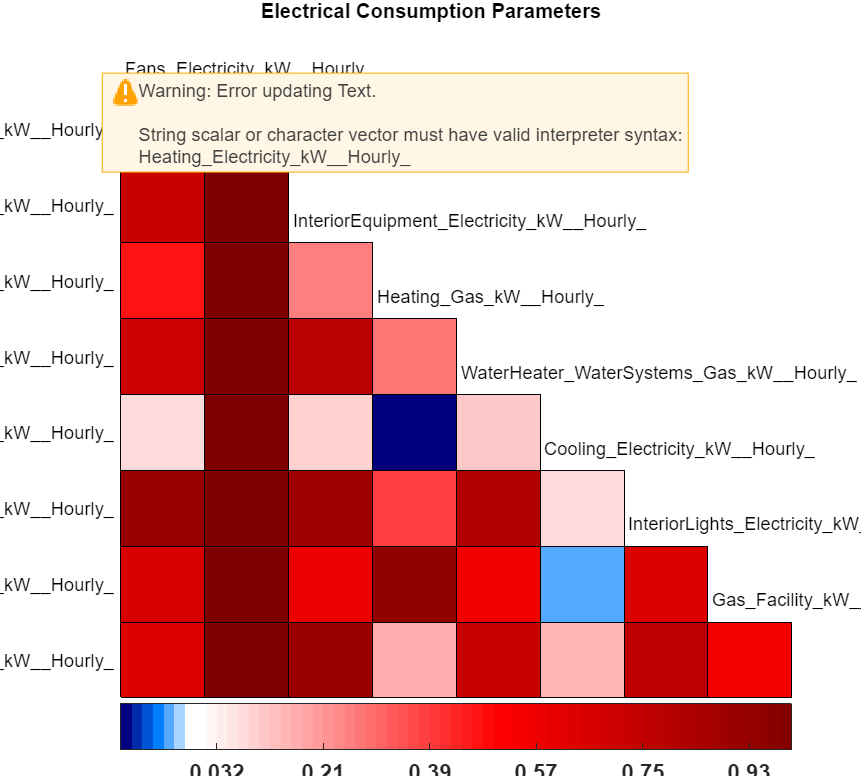

NewDataFeatures =     3.5862         0         0  136.5859
         0         0         0    3.3599
         0         0         0    3.3599
         0         0         0    3.9319
         0         0         0    3.3599
    3.5862    0.0132         0  130.5649
    3.5862    0.0074         0  140.4355
    3.5862    0.0075         0  135.4560
    3.5862         0         0  145.5751
    3.5862         0         0  147.6959


NewFeaturesLabels = 1×4 cell array
    {'Fans_Electricity_kW__Hourly_'}    {'Cooling_Electricity_kW__Hourly_'}    {'Heating_Electricity_kW__Hourly_'}    {'Gas_Facility_kW__Hourly_'}


LabelsRemove = 1×5 cell array
    {'InteriorLights_Electricity_kW__Hourly_'}    {'InteriorEquipment_Electricity_kW__Hourly_'}    {'Heating_Gas_kW__Hourly_'}    {'InteriorEquipment_Gas_kW__Hourly_'}    {'WaterHeater_WaterSystems_Gas_kW__Hourly_'}


%Maximum correlation value allowed
% Dafault 0.75
threshold = 0.75;

% El numero de variables a analizar debe ser igual al numero de nombres de
% variables
Features_labels=cellstr(varnames(2:end)');
%corrcoef(input)

% Example:
% a=[1:10];b=a+3;c=a.*b;
% corrcoef([a b c])
% 1.0000    1.0000    0.9816
% 1.0000    1.0000    0.9816
% 0.9816    0.9816    1.0000

[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(input,Features_labels,threshold)

%Variables eliminadas por superarf el threshold
LabelsRemove'

ans = 5×1 cell array
    {'InteriorLights_Electricity_kW__Hourly_'   }
    {'InteriorEquipment_Electricity_kW__Hourly_'}
    {'Heating_Gas_kW__Hourly_'                  }
    {'InteriorEquipment_Gas_kW__Hourly_'        }
    {'WaterHeater_WaterSystems_Gas_kW__Hourly_' }


%variables que se quedan por no superan el threshold en coreelacion
NewFeaturesLabels'

ans = 4×1 cell array
    {'Fans_Electricity_kW__Hourly_'   }
    {'Cooling_Electricity_kW__Hourly_'}
    {'Heating_Electricity_kW__Hourly_'}
    {'Gas_Facility_kW__Hourly_'       }


ejemplo=[input(1:end-1,4:5) output(2:end,1)]

ejemplo =     4.5899    8.1892   14.6498
    1.5300    7.4902   14.6696
    1.5300    7.4902   14.6778
    1.5300    7.4902   14.8248
    1.5300    7.4902   22.1826
    4.5899    8.1892   38.1318
    9.1799   19.4245   45.5973
    9.1799   26.9147   45.6036
    9.1799   26.9147   38.1138
    9.1799   19.4245   42.4352


clear threshold Features_labels;

## **Paso 9- Seleccionar el algortimo de ML con un menos error de prediccion empleando el toolbox de Matlab Regression Learner**

% Concatenando la variables de entrada actual con la salida en la hora
% siguiente
DataRegression=[NewDataFeatures(1:end-1,:) output(2:end,1)];
regressionLearner

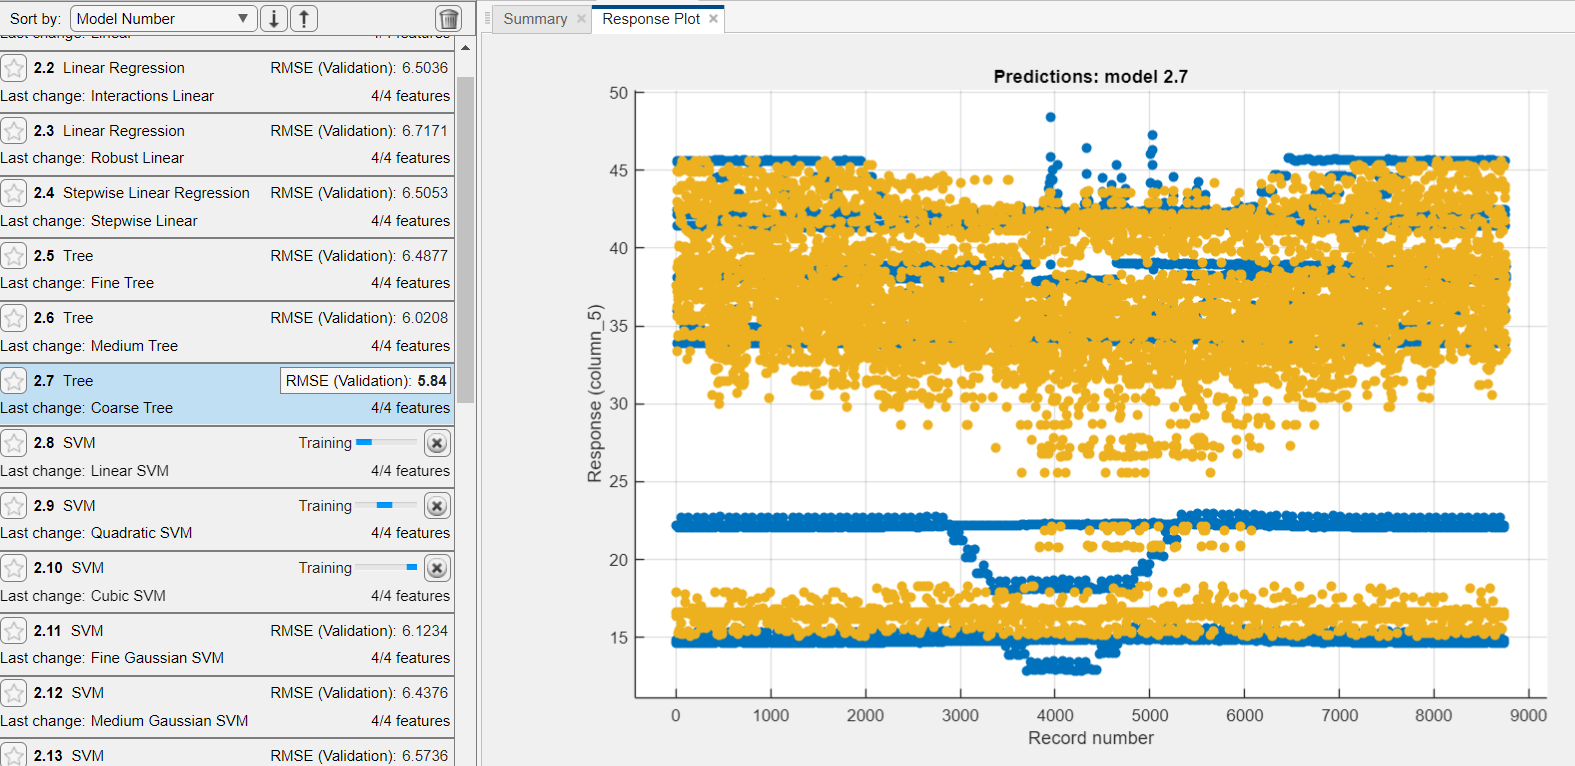

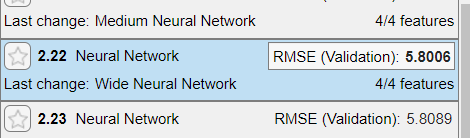     

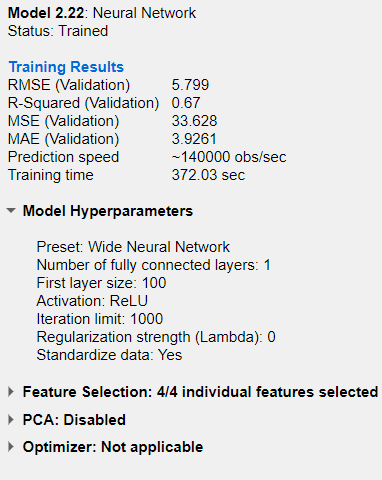

      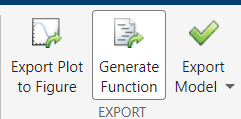

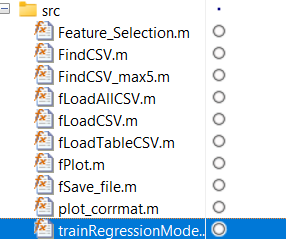

## **Paso 10- Dividir el dataset en 70% para entrenar y 30% validar**

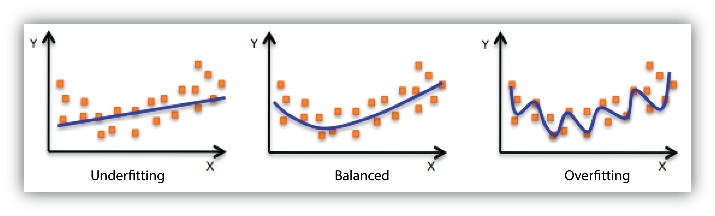

%Set de % de entrenamiento
% Dafault 0.70
PSplit = 0.7;

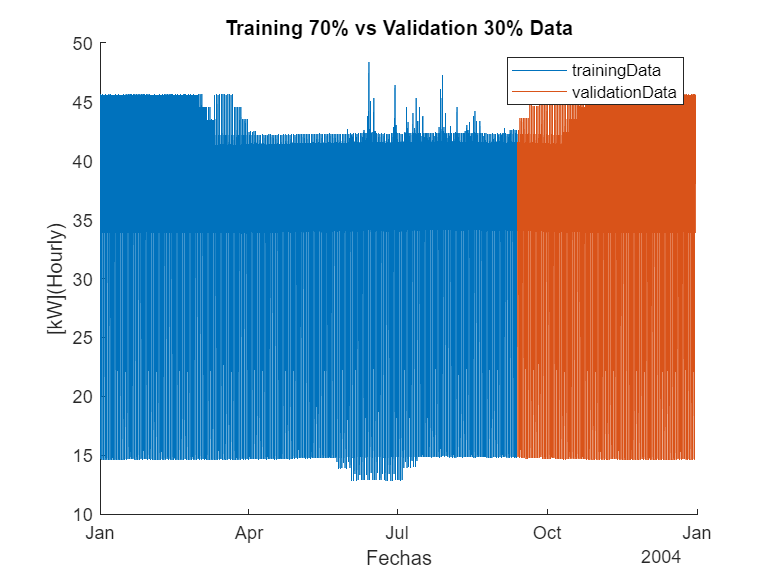

% Dataset de entrenamiento 70%
trainingData=DataRegression(1:round(end*PSplit),:);
traninTime=time(1:round(end*PSplit)-1);
% Dataset de validcion 30%
validationData=DataRegression(round(end*PSplit)+1:end,:);
validationTime=time(round(end*PSplit)+1:end);

figure;
% Dataset
hold on
plot(traninTime,trainingData(:,end))
plot(validationTime,validationData(:,end))
title(['Training ' num2str(PSplit*100) '% vs Validation '...
    num2str(100-PSplit*100) '% Data']);
xlabel('Fechas')
ylabel('[kW](Hourly)')
legend('trainingData','validationData')

## **Paso 11- Usando el algoritmo de ML se entrena el modelo de regression (costo computacional)**

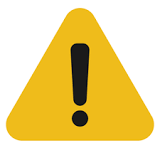

%Esta funcion permite generar un modelo actualizado cada vez que se ejecuta
% Siempre que el numero de variables de entrada sea la misma y la cantidad
% de nuevos datos no sea muy alta
[trainedModel, validationRMSE] = trainRegressionModel(trainingData);
%Este es el error de entrenaamiento
validationRMSE

validationRMSE = 5.9489

%Permite guardar el modelo entrenado que se encuentra en el workspace
save("trainedModel.mat","trainedModel")

## **Paso 12- Cargar y validar el modelo entrenado**

%Cargar el modelo entrenado y guardado
load("trainedModel.mat")

%Usar el modelo entrenado para predecir valores de consumo de energia
yest = trainedModel.predictFcn(validationData(:,1:end-1));

%El valor real de consumo de energia para comparar
yout = validationData(:,end);

%Error de prediccion con datos de validacion
validationRMSE = sqrt(mean((yest - yout).^2))

validationRMSE = 6.1812

## paso 13 - Graficar el valor predecido vs el valor real

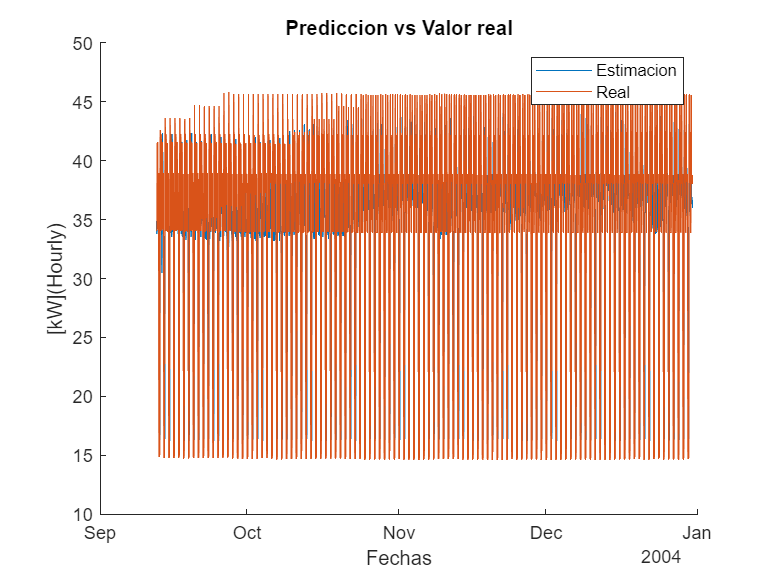

figure;
% Dataset
hold on
plot(validationTime,yest)
plot(validationTime,yout)
title('Prediccion vs Valor real');
xlabel('Fechas')
ylabel('[kW](Hourly)')
legend('Estimacion','Real')

## paso 14 - Mejorar el modelo de prediccion